# Perceptron simple NAND

#### Rodrigo Emmanuel Flores Avalos 

#### Redes Neuronales 8CV41

### Generación de datos

Como primer paso debemos definir la matriz que va a contener la tabla de verdad en la cual se va a basar todo nuestro proceso.

sample1=[-1,-1]; sample2=[-1,1];
sample3=[1,-1]; sample4=[1,1];

Definir la matriz y la compuerta.

X=[sample1;sample2;sample3;sample4]

X =     -1    -1
    -1     1
     1    -1
     1     1


Y=[1;-1;-1;-1];

Definir la linea que va a representar el hiperplano de separación.

w1=rand(); w2=rand(); th=rand();
x=-3/2:1/2:3/2;
y=(-w1/w2)*x+(-th/w2);

Graficar los datos.

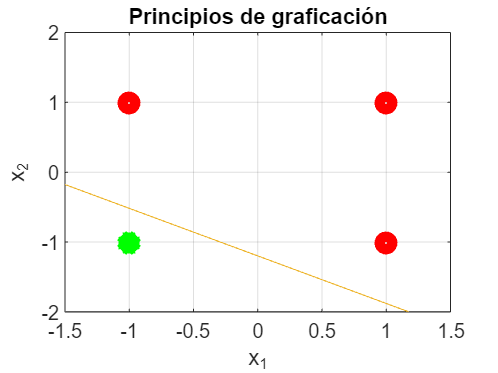

figure(1)
plot(X(2:4,1), X(2:4,2), 'ro', 'LineWidth', 5)
title('Principios de graficación')
xlabel('x_1')
ylabel('x_2')
axis([-3/2,3/2,-2,2])
grid on
hold on
plot(X(1,1),X(1,2),'g*', 'LineWidth',10)
plot(x,y)

### Proceso de aprendizaje

- Definir los pesos y el umbral de activación con valores aleatorios.

w1=rand(); w2=rand(); th=rand();

- Seleccionar el i-ésimo vector del conjunto de entrenamiento.

for i=1:1:size(X,1)
    aux=X(1,:);
end

- Calcular la y acumulada según la ecuación :

y_acumulada=((w1*x1)+(w2*x2))+theta.

for i=1:1:size(X,1)
    aux=X(1,:);
    y_acumulada=w1*aux(1,2)+w2*aux(1,1)+th;
end

- Calcular la y predicha según el paradigma en e que estemos (el actual es un paradigma bipolar).

for i=1:1:size(X,1)
    aux=X(1,:);
    y_acumulada=w1*aux(1,2)+w2*aux(1,1)+th;
    if y_acumulada>=0 
        y_pred=1;
    else
        y_pred=-1;
    end
end

- Calcular los pesos si es que la y predecida es diferente a y en el i-ésimo elemento son diferentes.

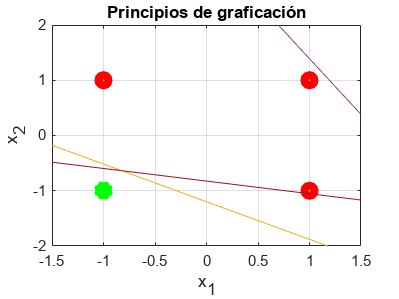

for i=1:1:size(X,1)
    aux=X(1,:);
    y_acumulada=w1*aux(1,2)+w2*aux(1,1)+th;
    if y_acumulada>=0 
        y_pred=1;
    else
        y_pred=-1;
    end
    if y_pred~=Y(i)
        delta_w1=Y(i)*aux(1,2);
        delta_w2=Y(i)*aux(1,1);
        delta_th=Y(i)*1;
        w1=w1+delta_w1;
        w2=w2+delta_w2;
        th=th+delta_th;
    end
    pause(2)
    y=(-w1/w2)*x+(-th/w2);
    plot(x,y)
end

Para poder moverse entre N epocas se puede realizar lo siguiente. Ejemplo para 10 epocas:

% for j=1:10
%     for i=1:1:size(X,1)
%         aux=X(1,:);
%         y_acumulada=w1*aux(1,2)+w2*aux(1,1)+th;
%         if y_acumulada>=0 
%             y_pred=1;
%         else
%             y_pred=-1;
%         end
%         if y_pred~=Y(i)
%             delta_w1=Y(i)*aux(1,2);
%             delta_w2=Y(i)*aux(1,1);
%             delta_th=Y(i)*1;
%             w1=w1+delta_w1;
%             w2=w2+delta_w2;
%             th=th+delta_th;
%         end
%         pause(2)
%         y=(-w1/w2)*x+(-theta/w2);
%         plot(x,y)
%     end
% end
